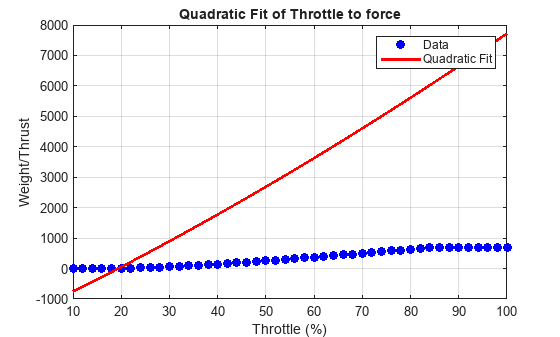

throttles = 10:2:100;
weights_thrust = [ 0.00, 0.00, 0.00, 0.00, 0.00, 4.00, 11.00, 19.00, 30.00, 42.00, 55.00, 70.30, 86.00, 102.70, 121.90, 142.90, 162.90, 184.60, 208.20, 229.40, 252.70, 274.30, 300.10, 323.30, 347.50, 371.70, 398.60, 423.20, 450.30, 474.20, 501.10, 531.80, 555.10, 582.40, 608.20, 635.10, 663.10, 690.40, 686.80, 685.20, 684.90, 685.50, 683.20, 680.50, 681.40, 679.20 ];

throttles_to_force = 9.81 / 1000 * weights_thrust;

p = polyfit(throttles, throttles_to_force, 2);

x_fit = linspace(min(throttles), max(throttles), 500);
y_fit = polyval(p, x_fit);

figure;
plot(throttles, weights_thrust, 'bo', 'MarkerFaceColor', 'b'); % data points
hold on;
plot(x_fit, y_fit, 'r-', 'LineWidth', 2); % quadratic fit
xlabel('Throttle (%)');
ylabel('Weight/Thrust');
title('Quadratic Fit of Throttle to force');
legend('Data', 'Quadratic Fit');
grid on;